Implementation of Computational Ocean Acoustics pressure update equation from pg 558 for 2D ocean.

%Defining constants, dimensions and positions
k = 1.0e-5; %time step
h = 0.02;   %spatial step - is a wave, but pressure gets really large
%h= 0.2; %stops pressure from becoming really large but isn't a wave
c = 1500;   %speed of sound in water in m/s
r = (c*k)/h%step ratio (must be less than or equal to one)

r = 0.7500

time = 0;   %variable to keep track of time
simLength = 0.001;  %simulation length (s)
maxN = round(simLength/k); %total number of frames
colDims = [1,1]; %dimensions of the water column (meters)
colDimsD = round(colDims/h); %column dimensions in nodes
srcPos = [0.5,0.5];     %source position (meters)
srcPosD = round(srcPos/h); %source position in nodes
recPos = [0.6,0.5];   %receiver position (meters)
recPosD = round(recPos/h); %receiver position in nodes
backscatter = zeros(maxN,1); % Array to store backscatter data 

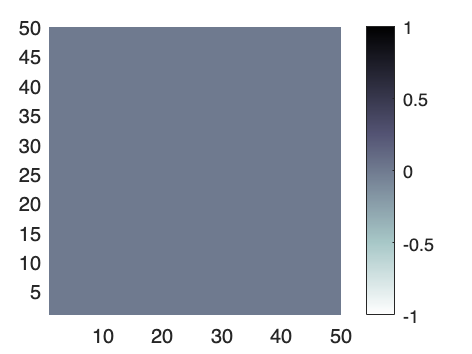

p = zeros([colDimsD 3]); %initialise pressure matrix
% Fourth dimension is discrete time
% (:,:,:,1) is (n+1)
% (:,:,:,2) is (n)
% (:,:,:,3) is (n-1)
%Setting up the plot
pl = abs(p(:,:,1)); %absolute value of pressure
h2 = pcolor(pl); colormap(flipud(bone));
colorbar;
xlim([1 colDimsD(1)]);
ylim([1 colDimsD(2)]);
shading interp;

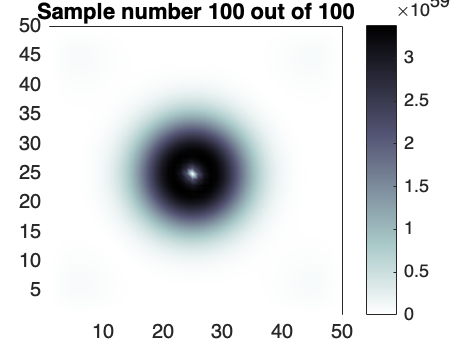

% Define shift vectors
ll=2:colDimsD(1)-1;
mm=2:colDimsD(2)-1;

%constants for the gaussian pulse
f0 = 50; %center frequency of the pulse (Hz)
t0 = 0.1; %time offset of the pulse (s)
sigma = 0.1; %standard deviation of the Gaussian (s)

%running the simulation
for nn=1:maxN
    time = time + k;
    %update equation
    p_new(ll,mm) = r^2.*(p(ll-1,mm,2)+p(ll+1,mm,2)+p(ll,mm-1,2)+p(ll,mm+1,2))...
        + 2*(1-((2*r^2).*p(ll,mm,2))) - p(ll,mm,3);
    p(ll,mm,1) = p_new(ll,mm);
    
    %adding source (using additive source from EM FDTD book
    %exp(-(qTime-30.0)*(qTime-30.0)/100.0)
    %pulse = exp(-(time-(30*k))^2 /(100*k));
    pulse = exp(-(time-t0).^2/(2*sigma^2)).*sin(2*pi*f0*(time-t0));%pulse stays small (as expected)
    p(srcPosD(1),srcPosD(2),1) = p(srcPosD(1),srcPosD(2),2) + pulse;

    %shifting time
    p(:,:,3) = p(:,:,2);
    p(:,:,2) = p(:,:,1);
    
    pl = abs(p(:,:,1));
    backscatter(nn) = p(recPosD(1),recPosD(2),2);
    set(h2,'CData',pl);
    title(sprintf('Sample number %d out of %d',nn,maxN));
    drawnow;
end

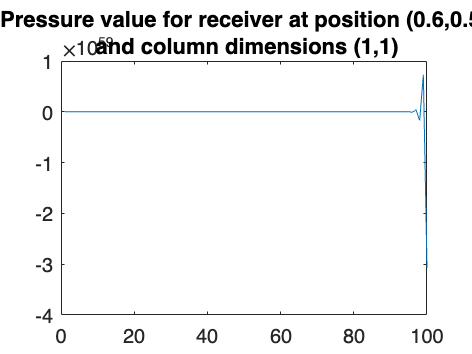

plot(backscatter)
title({ ...
    ['Pressure value for receiver at position (' num2str(recPos(1)) ',' num2str(recPos(2)) ')'] ...
    [' and column dimensions (' num2str(colDims(1)) ',' num2str(colDims(2)) ')'] ...
    })

%{
title({ ...
    ['Pressure value for receiver at position (' num2str(recPos(1)) ',' num2str(recPos(2)) ',' num2str(recPos(3)) ')'] ...
    [' and room dimensions (' num2str(roomDims(1)) ',' num2str(roomDims(2)) ',' num2str(roomDims(3)) ')'] ...
    })
%}